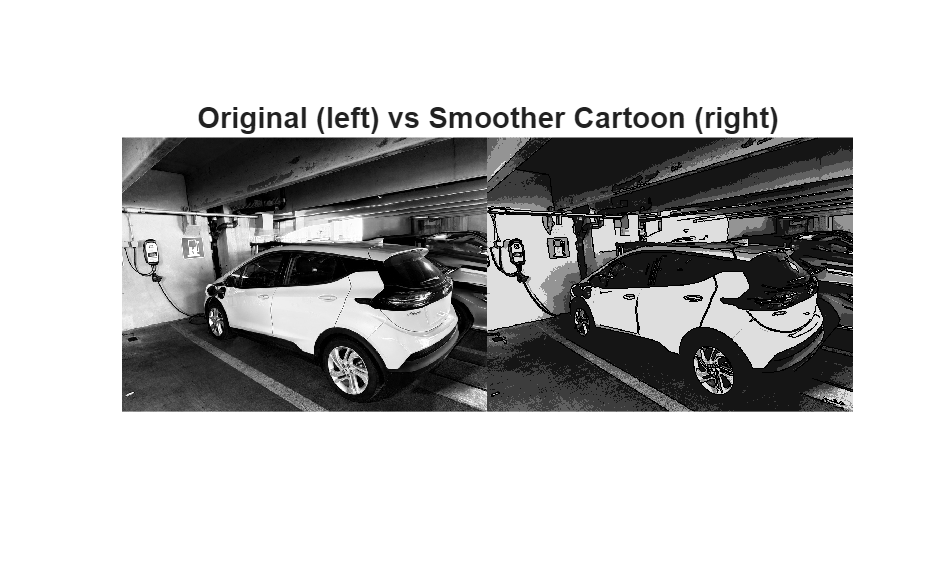

% Cartoonize a photo (color quantization + edge overlay)
I = imread("EVCharge.jpg");              % <-- change filename

I = im2uint8(I);

% 1) Edge-preserving smoothing (smoother "painted" regions)
% DegreeOfSmoothing controls how strong the smoothing is
% SpatialSigma controls how far the filter reaches (in pixels)
Is = imbilatfilt(I, 0.12, 8);              % try (0.05–0.15, 3–10)  [1](https://mathworks.atlassian.net/wiki/spaces/PARCG/pages/1004830305/IPT+functions)[2](https://mathworks.atlassian.net/wiki/spaces/PARCG/pages/161197143/imbilatfilt)

% 2) Reduce colors (posterize)
K = 5;                                     % fewer = flatter/smoother regions
[idx, cmap] = rgb2ind(Is, K, "nodither");
Iq = im2uint8(ind2rgb(idx, cmap));

% 3) Cleaner edges (less noisy)
G  = rgb2gray(Is);
E  = edge(G, "Canny", [0.08 0.20]);         % adjust thresholds to reduce speckles
E  = imclose(E, strel("disk", 1));          % connect broken lines
E  = bwareaopen(E, 30);                     % remove tiny edge fragments
E  = imdilate(E, strel("disk", 1));         % thicken outline a touch

% 4) Overlay edges as black ink
Icartoon = Iq;
Icartoon(repmat(E,[1 1 3])) = 0;

% Save Icartoon as a PNG
imwrite(Icartoon, "Icartoon.png", "png");

imshowpair(I, Icartoon, "montage")
title("Original (left) vs Smoother Cartoon (right)")